# Optical Centrifuge for Diatomic Molecules: Zero-Velocity Surface

        Last modified by Cristel Chandre (July 7, 2022)

        Comments? [cristel.chandre@cnrs.fr](mailto:cristel.chandre@cnrs.fr) 

        Zero-velocity surface given by $V_{\rm 2D}(r,\phi) = -\frac{1}{2} \mu \omega_L^2 r^2+\varepsilon(r)
-\frac{F_0^2}{4} [\Delta \alpha(r) \cos^2\phi+\alpha_\bot(r)]$

omL = 0;
F0 = 1e-2;

plot_potentials = true;
plot_ZVS = false;

re = 3.756;
De = 0.0915;
gam = 1.0755;
mu = 32548.53;
acl = 15.5421;

N = 2^8;

eps = @(r) De*(1-exp(-gam*(r-re))).^2-De;
Dal = @(r) alpara(r,re,acl)-alperp(r,re,acl);
ZVSpot = @(r,phi) -mu*omL^2*r.^2/2+eps(r)-...
    F0^2/4*(Dal(r).*cos(phi).^2+alperp(r,re,acl));

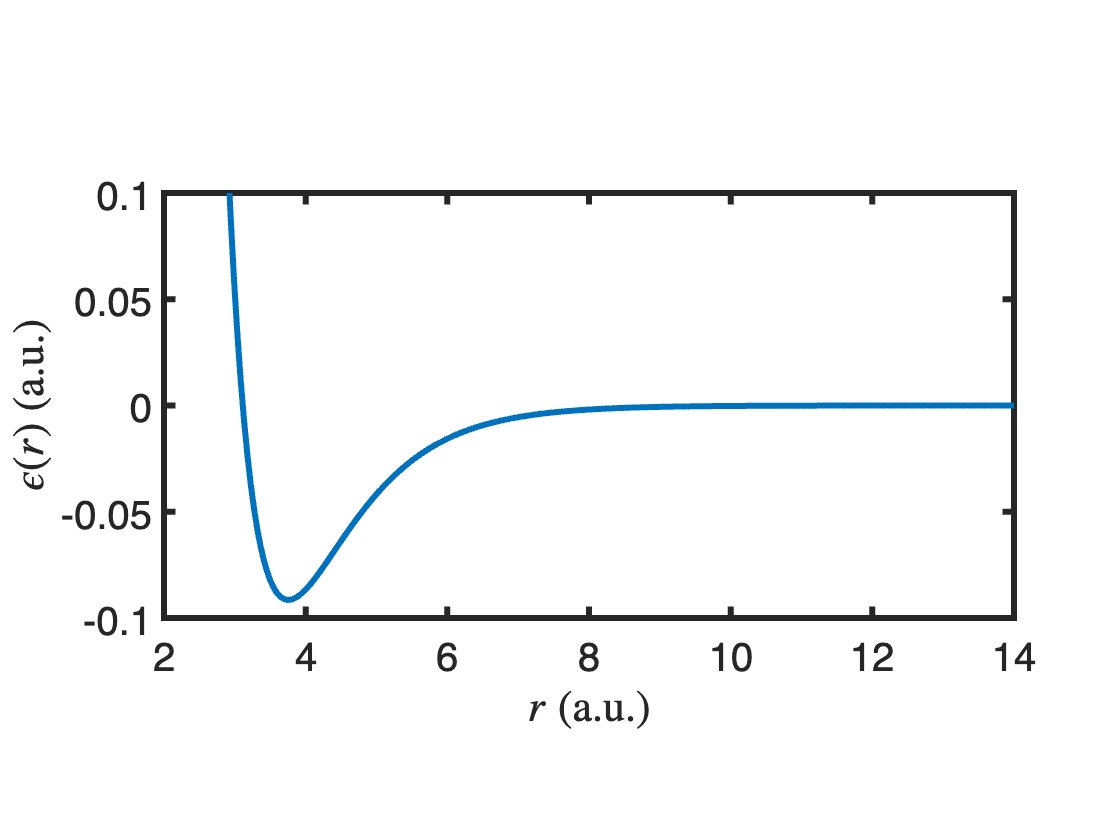

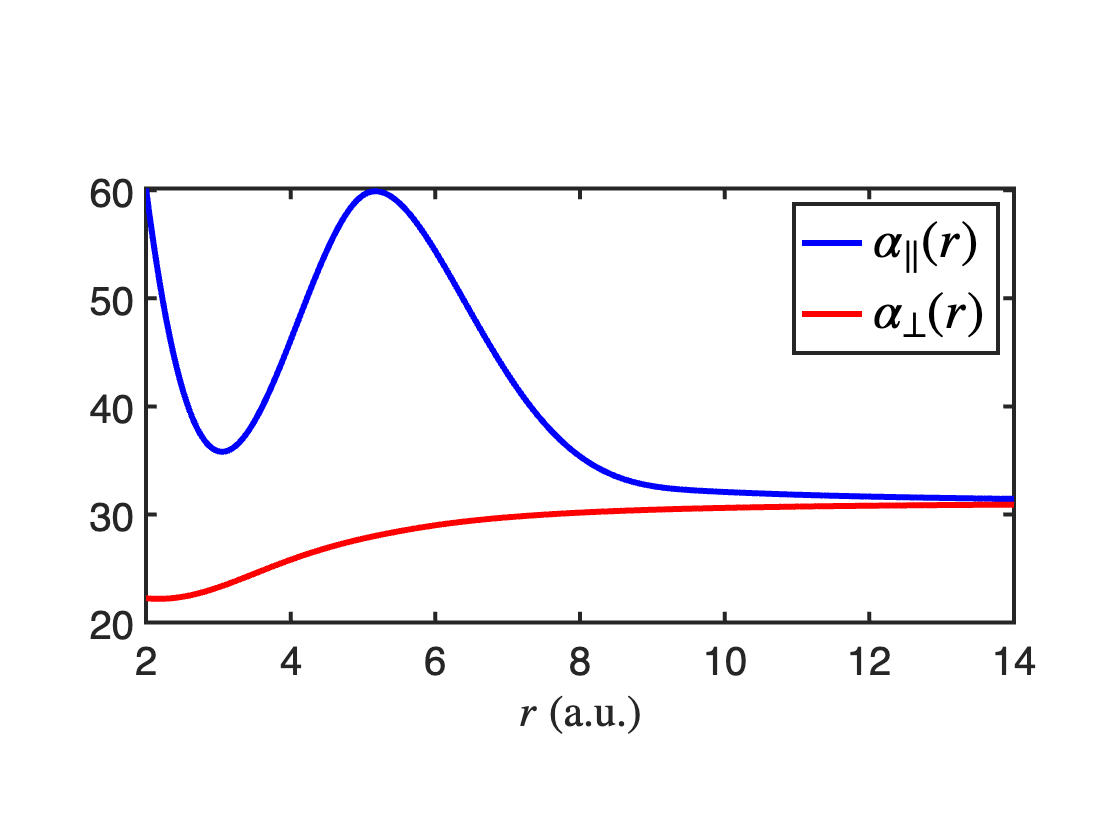

if plot_potentials
    r = linspace(2,14,N);
    figure, plot(r,eps(r),'LineWidth',3)
    pbaspect([2 1 1])
    xlim([2 14])
    ylim([-0.1 0.1])
    xlabel('$r$ (a.u.)','interpreter','latex','FontSize',26)
    ylabel('$\epsilon(r)$ (a.u.)','interpreter','latex','FontSize',26)
    set(gca,'box','on','FontSize',20,'LineWidth',3)
    figure, p1 = plot(r,alpara(r,re,acl),'b','LineWidth',3);
    hold on, p2 = plot(r,alperp(r,re,acl),'r','LineWidth',3);
    pbaspect([2 1 1])
    xlabel('$r$ (a.u.)','interpreter','latex','FontSize',26)
    set(gca,'box','on','FontSize',20,'LineWidth',2)
    legend([p1 p2],{'$\alpha_\parallel(r)$','$\alpha_\perp(r)$'},'interpreter','latex','FontSize',26)

end

if plot_ZVS
    r = linspace(20,70,N);
    phi = linspace(-pi,pi,N);
    [R, Phi] = meshgrid(r,phi);
    figure,contourf(phi,r,ZVSpot(R,Phi).',50)
    xlabel('$\phi$','interpreter','latex','FontSize',26)
    ylabel('$r$ (a.u.)','interpreter','latex','FontSize',26)
    title('Zero-Velocity Surface')
    set(gca,'box','on','FontSize',20,'LineWidth',2,'YDir','normal')
end

function val = alperp(r,re,acl)
valSR = 25.29+2.87*(r-re)-0.09*(r-re).^2-0.42*(r-re).^3;
valLR = (2*acl-2*acl^2./r.^3)./(1-acl^2./r.^6);
valMR = 68.28948313113857-56.39145030911223*r+...
    25.523842390023567*r.^2-5.33917063891859*r.^3+...
    0.5409284377558191*r.^4-0.02155141584655734*r.^5;
val = valSR.*(r<=3)+valMR.*((r>3)&(r<=6))+valLR.*(r>6);
end

function val = alpara(r,re,acl)
valSR = 42.13+15.4*(r-re)+5.4*(r-re).^2-5.25*(r-re).^3;
valLR = (2*acl+4*acl^2./r.^3)./(1-4*acl^2./r.^6);
valMR = -1599.0948228665286+1064.701691434201*r-...
    262.7958617988855*r.^2+31.287242627165202*r.^3-...
    1.8164825476900417*r.^4+0.04141328363593082*r.^5;
val = valSR.*(r<=5)+valMR.*((r>5)&(r<=10))+valLR.*(r>10);
end

Copyright (c) 2022 Cristel Chandre.

All rights reserved.

Redistribution and use in source and binary forms are permitted provided that the above copyright notice and this paragraph are duplicated in all such forms and that any documentation, advertising materials, and other materials related to such distribution and use acknowledge that the software was developed by the CNRS. The name of the CNRS may not be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED "AS IS" AND WITHOUT ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, WITHOUT LIMITATION, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE.